% Simulation of the Unloaded and Loaded B_scans, assuming:
% - Uniform strain in the region and
% - The scattered field is approximated as spherical waves originating from the scatterers
% - Illumination is modelled with the Debye-Wolf integral:


$$E(x,y,z;\nu) = -\frac{i \nu f}{c}\int\int\limits_\Omega {{u}}\left({s}\right)\frac{e^{-\left(\frac{\nu}{W }\right)^2|{s}|^2}}{\sqrt{1-|{s}|^2}}e^{i2 \pi\frac{ \eta \nu} {c}\left({x {s_x}+y s_y} +  \left(z-z_{f}\right)\sqrt{1-|{s}|^2} \right)}ds_xds_y; \qquad \Omega  = \left\{ (s_x,s_y) \in \rm I\!R^2\left| \sqrt{s_x^2+s_y^2} < \frac{NA}{\eta} \right.\right\}$$



$$\nu = \frac{k}{2\pi} = \frac{1}{\lambda} \quad \text{  is the spatial frequency}; \quad z = z_f \quad \text{ is the focal plane.}$$


% The coordinate system is originated at the "mirror plane"
% -->  z = 0 is the mirror plane,  z = z_f is the focal plane of the beam.

clear all; clc;   % Inizialization

TEST = 1;


laptop = 'C:\Users\andre\Documents\MATLAB/Matlab_drive_scripts/'; % Desktop personal folder
desktop = '/home/andrea/MATLAB_26_04_2022/Matlab_drive_scripts/'; % Desktop personal folder
remote = '/home/amazzolani/Matlab_drive_scripts/'; % personal folder in Mnemosine/zeus

if isfolder(laptop)
    path_str = laptop;
elseif isfolder(desktop)
    path_str = desktop;
elseif isfolder(remote)
    path_str = remote;
end

addpath(genpath([path_str,'handle_functions']));
addpath(genpath([path_str,'OCT_models/Simulated_OCT_DW_UL_Bscan']));
addpath(genpath([path_str,'Illumination_functions']));
addpath(genpath([path_str,'saved_heavy_files']));

% Set the Matlab current folder where the folder --> "Simulated_OCT_DW_UL_Bscan" was copied
%cd([path_str,'OCT_models/Simulated_OCT_DW_UL_Bscan'])

tic;

% Folders to add to the path
DW_signal_folder = [path_str,'My_papers_code/Fast_OCT_simulations/saved_data'];
str_folder = [DW_signal_folder,'/' ...%dfgag'];%
    'Acc_vs_Time_1469_Nscanx_1_Nscany_1_Nv_10240_Zmin_1300_Zmax_1.7e+03_zf_0_alpha_0_0_NL_1_NA_1.mat'];
     
%     'Acc_vs_Time_960_Nscanx_1_Nscany_1_Nv_10000_Zmin_1000_Zmax_1.11e+03_zf_0_alpha_0_0_NL_1_NA_1.mat']
%  'Test_dataset_96_Nscanx_11_Nscany_1_Nv_20000_Zmin_0_Zmax_110_zf_0_alpha_0_0_NL_1_NA_1.mat']

if   not(isfolder(remote))&(exist(str_folder) == 2)
    DL = load(str_folder); if (isfield(DL,"DL")); DL = DL.DL; end; unpackStruct(DL);
else
    answer = input('There are not loaded files, do you still want to proceed?','s');
    while not((answer == "n")|(answer == "y"))
        answer = input(['Answer y or n:\n'],'s');
    end
    if answer == "n"
        error(["Check the file name!"]);
    end

    c = 2.997924580105029e+08;  % speed of light

    %%%%%%%%%%%%%%%%%%%     Parameters of the simulation   %%%%%%%%%%%%%%%%%%%%%%%%
    % Scatterers region
    refind = 1;
    z_f = 0e-6/refind; % Axial coordinate of the focus of the Gaussian beam: 'z_f > 0'  -->  the mirror is placed at the left of the focal plane of the objective lens
    LX = 80e-6;     % Maximum lateral position of the scatterers in x direction (meters)
    LY = 80e-6;     % Maximum lateral position of the scatterers in y direction (meters)
    minZ = 1300e-6;   % minimum of the scatterers axial position (meters)
    maxZ = 1700e-6;  % maximum of the scatterer axial  position (meters) (meters)
    DZ = maxZ - minZ; % Width of the axial interval
    nn3_dens = 1; % Number of scatterers for ( 10 micron)^3
    Nv = round( 2*LX*2*LY*DZ/(10e-6^3)*nn3_dens); % The number of scatterers is usually set as a function of the region volume

    % Layers of strains
    dalpha = 11e-4;
    alpha_min = 0e-3;
    alpha_max = 0e-3;
    NA_tot = 1;
    Nalpha_conf = 1;NA_tot*2 + 1;
    Nalpha_layers = 1; % Number of uniform layers for each combination
    alpha_VEC = 0; linspace(alpha_min + 0.*dalpha/2,alpha_max - 0.*dalpha/2,Nalpha_conf).';% alpha_min + rand(Nalpha_conf,Nalpha_layers) * (alpha_max-alpha_min);
    %   ALPHA = ones(Nalpha_conf, Nalpha_layers).*alpha_VEC;% + (rand(Nalpha_conf, Nalpha_layers)-0.5).*dalpha;
    ALPHA = zeros(Nalpha_conf, Nalpha_layers);

    %     ALPHA(2:NA_tot+1,1) = 1e-3.*([1:NA_tot].*3).'; ALPHA(2:NA_tot+1,2) = ALPHA(2:NA_tot+1,1);
    %     ALPHA(NA_tot+2:NA_tot*2+1,1) = 1e-3.*([1:NA_tot].*3).'; ALPHA(NA_tot+2:NA_tot*2+1,2) = 1e-3.*10;
    Nbord = Nalpha_layers-1; % it defines Nbord + 1 uniform strains for each C-scan
    borders = zeros(1,Nbord+2);        % Borders of the layers of strains
    borders(1) = minZ;                  % 1-st boarder must be smaller or equal to the shallowest scatterer z-coordinate
    borders(Nbord+2) = maxZ;           % the last boarder must be greater or equal to the deepest scatterer z-coordinate
    borders(2:Nbord+1)  = minZ + [1000]*1e-6;  % Choose the coordinates of the borders of the middle layers! ( borders (2:N-1));
    BORD = ones(Nalpha_conf, Nalpha_layers + 1).*borders;


    % Control statements to check that the array of borders has been set correctly.
    if (min(min(diff(BORD,[],2))) < 0);
        error(["Borders must be an increasing array! Borders coordinates originate at the focal plane. "])
    end
    if sum((BORD(1,:) < minZ)) > 1;
        error(["First border must be less or equal than the shallowest scatterers "]);
    end

    % Reflectivity coefficients of the scattererss
    rhoMax = 3e-4; % Maximum of the reflectivity profile (This is a relative parameter, considering the mirror reflectivity = 1!!);

    % Lateral scanning p-arameters
    dscan = 0.7e-6;
    Max_scan = LX - 10e-6; % Maximum lateral scanning in positive and negative x-direction (meters)
    Nscanx = 1; ceil(2*Max_scan/dscan); % Number of A-scan for each B-scan
    if (Nscanx == 1); x_scan_vec = 0e-6; y_scan_vec = -0e-6; Nscany = Nscanx; else; x_scan_vec = linspace(-Max_scan,Max_scan,Nscanx); y_scan_vec = 0; Nscany = length(y_scan_vec); end;
    % Nscany = 1; y_scan_vec = 0; Nscanx0 = ceil(Nscanx/2)+1; Nscanx = 2*Nscanx0-1; x_scan_vec = linspace(-Max_scan,Max_scan,Nscanx);
    % Uniform refractive index of the medium
    y_scan_vec = 0; x_scan_vec; Nscany = length(y_scan_vec);

    % The following physical parameters have been set as the OCT at UCL
    W_0 = 4.6e-6; % Waist radius of the Gaussian beam at the aperture plane between the collimator and the objective lens
    NA = 0.0972;   % Numerical aperture (Ra = NA*foc2 --> NA = Ra/foc2)
    %   Ra = 3.5e-3; % Radius of the aperture
    %   NA = Ra/foc2;
    lam_min = 1170.5e-9;  % minmum wavelength (meters)
    lam_max = 1407.8e-9;  % maximum wavelength (meters)

    foc1 = 25*1e-3; % focal length of the collimator (meters)
    foc2 = 36*1e-3; % focal length of the objective lens (meters)
    %     Ra = 3.5e-3;

    % Dependent parameters
    rho = rand(1,Nv).*rhoMax; % Array of the reflectivity profiles of all scatterers (It is set random)
    b12 = foc1/foc2;  % ratio between the focal lenghts ( This parameter is used in the Debye-Wolf integral)
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


    %%%%%%%%%%%%%%    Unloaded scatterer region setting    %%%%%%%%%%%%%%%%%%%%%%
    v_U = zeros(Nv,3); % Array of scatterers initialization: 2D array of the scatterers in the unloaded case. This is an array of dimension (Nv,3), where each row consists of 3 numbers that are the (x,y,z) coordinates of each scatterer
    v_U(:,1) = -LX + rand(Nv,1)*2*LX; % (x coordinates of all scatterers)
    v_U(:,2) = -LY + rand(Nv,1)*2*LY; % (y coordinates of all scatterers)
    v_U(:,3) = sort(minZ + rand(Nv,1)*DZ);  % (z coordinates of all scatterers)
    %   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%%%%%%%%%%%%%     Spatial frequency setting  'f = 1/lambda'    %%%%%%%
    f_min = 1./lam_max;  % minimum frequency of the simulated spectrum
    f_max = 1./lam_min;  % maximum frequency of the simulated spectrum
    f0 = ( f_max + f_min)/2; % central frequency of the simulated spectrum
    Df = f_max - f_min; % frequencies spectrum width
    Nk_nyq = 4*max(abs(v_U(:,3).*refind))*Df; % Minimum number of frequencies able to simulate the deepest axial position (coming from the Nyquist frequency and rates relation)

    Nk =  ceil(Nk_nyq*1.5); % Number of wavenumbers, they are set as 1.5 times 'Nk_nyq' ( A safe number greater than 'Nk_nyq')
    f_vec = linspace(f_min,f_max,Nk);  % Spatial-frequencies array
    f_vec_t = f_vec.*c; % Time-frequencies_array
    k_vec = 2*pi*f_vec; % Arrays of wavenumbers;

    % Display of the chosen parameters (This is useful for simulations with Zeus or Mnemosine)
    if isfolder(remote)
        fprintf(['\n\nParameters:\n Nv = ', num2str(Nv), ' --> Total number of scatterers \n' ...
            ' Nscanx = ', num2str(Nscanx), ' --> Number of A-scans for each B-scan\n Max_scan = ', num2str(Max_scan*1e6) 'mum --> Maximum lateral scanning (left & right)\n LX = ', num2str(LX*1e6), ...
            'mum --> Maximum lateral distance of the scatterers in x direction (meters)\n LY = ', num2str(LY*1e6)...
            ,'mum --> Maximum lateral distance of the scatterers in y direction (meters)\n Nk = ', num2str(Nk),' --> Number of frequencies calculated in the simulation\n rhoMax = ', num2str(rhoMax), ' --> Maximum reflectivity profile of the scatterers\n z_f = ', num2str(z_f*1e6), 'mum --> Axial coordinate of the focus of the Gaussian beam ' ...
            '\n minZ = ', num2str(minZ*1e6), 'mum --> Minimum axial coordinate of the scatterers:\n maxZ = ', num2str(maxZ*1e6), 'mum --> Maximum axial coordinate of the scatterers:\n'...
            , ' Nalpha_layers = ', num2str(Nalpha_layers), '\n Nalpha_conf = ', num2str(Nalpha_conf), ' --> Number of configurations of series of strains. (Each configuration is related to a C-scan)\n alpha_min = ', num2str(alpha_min), '\n alpha_max = ', num2str(alpha_max), '\n refind = ', num2str(refind),'  --> Refractive index (uniform)\n'...
            ,'\nTotal number of A-scans to simulate: ', num2str(Nscanx*Nscany*Nalpha_conf),'\n']);

        answer = input(['\nProceed with those parameters? y/n:\n'],'s');
        while not((answer == "n")|(answer == "y"))
            answer = input(['Answer y or n:\n'],'s');
        end
        if answer == "n"
            error(["Update the parameters list run the script again!"]);
        end
    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Scattered field and modal coefficients calculation (First Born approximation)


$$\alpha_{sc}(\nu)  = \int\limits_{-\infty}^{+\infty}\int\limits_{-\infty}^{+\infty} E_x^{SC}(x,y,z_{obs};\nu)\hat{\phi}(x,y,z_{obs});\nu)d_xd_y
\approx\sum_j\rho_j\cdot(E_x(x_j,y_j,z_j;\nu))^2 ; \qquad \rho_j = \text{Reflectivity coefficient of the scatterer in } (x_j,y_j,z_j)$$


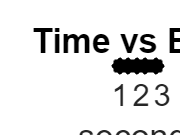

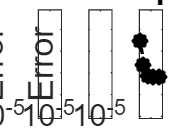

Unrecognized function or variable 'conventional_reconstruct'.


    global T_time LB NB Nderx_glob Nderz_glob ak_glob;

    ak_glob = [];
    % subset of data for the test
    iaconf0 = 1; Nk_sub = Nk; min(11,Nk); ik_sub = round(linspace(1,Nk,Nk_sub)).'; % subnumber of wavelenghts
    Nx_sub = Nscanx; min(2,Nscanx); ix_sub = round(linspace(1,Nscanx,Nx_sub)).'; % subnumber of lateral x-scanning
    Ny_sub = Nscany; min(2,Nscany); iy_sub = round(linspace(1,Nscany,Ny_sub)).'; % subnumber of lateral y-scanning

    % Rigorous calculation of the cross-correlation auto-correl. terms (...etc )for  the chosen sample of data.
    T_time = 0; LB = 1; NB = 1; 
    [alpha_output_tmp,IT_CCg_tmp] = Series_Loaded_DW_Cscan_uniform_Taylor15(v_U,rho,f_vec_t(ik_sub),refind,W_0/b12,NA,z_f,BORD,ALPHA,x_scan_vec,y_scan_vec);
    s = seconds(T_time); s.Format = 'hh:mm:ss'; %  T_taylor(iderx,iderz) = T_time;

    T_time = 0; LB = 1; NB = 1;
    [IT_CC_rig, IT_CC_AC_rig,IT_DC_sc_rig,IT_DC_ref_rig,ak_sc_rig,ak_ref_rig] = I_DW_Cscan(v_U,rho,f_vec_t(ik_sub),refind,W_0/b12,NA,z_f,x_scan_vec(ix_sub),y_scan_vec(iy_sub));
    t_rig = T_time; s_rig = seconds(T_time); s_rig.Format = 'hh:mm:ss'; s_rig

    vec_der_x = 5+ [0:3:15]; Nderx = length(vec_der_x);
    vec_der_z = 0:5; Nderz = length(vec_der_z);
    T_taylor = zeros(Nderx,Nderz); ERROR_T = zeros(Nderx,Nderz);
    IT_CC_TOT = zeros(Nk,Nscanx,Nderx,Nderz); IT_CC_rig = squeeze(IT_CC_rig);

    Nzx = 5; Err_tayg = zeros(Nzx,1); Err_tayg2 = zeros(Nzx,1); Err_tay = zeros(Nzx,1);
    T_tay = zeros(Nzx,1); T_tayg = zeros(Nzx,1); T_tayg2 = zeros(Nzx,1);

    for izx = 1:Nzx
        T_time = 0; LB = 1; NB = 1; Nderx_glob =  vec_der_x(Nderx-Nzx+izx); Nderz_glob = vec_der_z(Nderz-Nzx+izx);
        [alpha_output,IT_CCg, IT_CC_AC,IT_DC_sc,IT_DC_ref,akT_sc,akT_ref,ERROR_mat] = Series_Loaded_DW_Cscan_uniform_Taylor15(v_U,rho,f_vec_t,refind,W_0/b12,NA,z_f,BORD,ALPHA,x_scan_vec,y_scan_vec);
        s = seconds(T_time); s.Format = 'hh:mm:ss'; %  T_taylor(iderx,iderz) = T_time;
        T_tayg(izx) = T_time;

        %         [alpha_output,IT_CCg2, IT_CC_AC,IT_DC_sc,IT_DC_ref,akT_sc,akT_ref,ERROR_mat] = Series_Loaded_DW_Cscan_uniform_Taylor17(v_U,rho,f_vec_t,refind,W_0/b12,NA,z_f,BORD,ALPHA,x_scan_vec,y_scan_vec);
        %         s = seconds(T_time); s.Format = 'hh:mm:ss'; %  T_taylor(iderx,iderz) = T_time;
        %         T_tayg2(izx) = T_time;
        
        %         [alpha_output,IT_CC, IT_CC_AC,IT_DC_sc,IT_DC_ref,akT_sc,akT_ref,ERROR_mat] = Series_Loaded_DW_Cscan_uniform_Taylor5(v_U,rho,f_vec_t,refind,W_0/b12,NA,z_f,BORD,ALPHA,x_scan_vec,y_scan_vec);
        %         s = seconds(T_time); s.Format = 'hh:mm:ss'; %  T_taylor(iderx,iderz) = T_time;
        %         T_tay(izx) = T_time;

        fprintf(['Done ', num2str(izx),'/',num2str(Nzx),'\n']);
        Err_tayg(izx) = err_n(IT_CCg,IT_CC_rig);

        %         Err_tayg2(izx) = err_n(IT_CCg2,IT_CC_rig);
        %         Err_tay(izx) = err_n(IT_CC,IT_CC_rig);
    end

    %     for iderx = 1:Nderx
    %         for iderz = 1:Nderz
    %             idxz = iderz + (iderx-1)*Nderz; Ndxz = Nderx*Nderz;
    %             T_time = 0; LB = 1; NB = 1; Nderx_glob = vec_der_x(iderx); Nderz_glob = vec_der_z(iderz);
    %             [alpha_output,IT_CC, IT_CC_AC,IT_DC_sc,IT_DC_ref,akT_sc,akT_ref,ERROR_mat] = Series_Loaded_DW_Cscan_uniform_Taylor5(v_U,rho,f_vec_t,refind,W_0/b12,NA,z_f,BORD,ALPHA,x_scan_vec,y_scan_vec);
    %             s = seconds(T_time); s.Format = 'hh:mm:ss';   T_taylor(iderx,iderz) = T_time;
    %             fprintf(['Done ', num2str(idxz),'/',num2str(Ndxz),'\n']);
    %             ERROR_T(iderx,iderz) = err_n(IT_CC,IT_CC_rig);
    %             IT_CC_TOT(:,:,iderx,iderz) = IT_CC;
    %         end
    %     end

    % The following lines concerns the file name where I save the data in a struct file.
    str_a = [num2str(alpha_min),'_',num2str(alpha_max),'_NL_',num2str(Nalpha_layers),'_NA_',num2str(Nalpha_conf)];
    str = [DW_signal_folder,'/Acc_vs_Time_',num2str(Nk),'_Nscanx_',num2str(Nscanx),'_Nscany_',num2str(Nscany),'_Nv_',num2str(Nv),'_Zmin_',num2str(minZ*1e6),'_Zmax_',num2str(maxZ*1e6,3),'_zf_',num2str(z_f*1e6,3),'_alpha_',str_a,'.mat'];
    save(str,'f_vec','f_vec_t','k_vec','Nscanx','Nscany','dscan','Nk','Nv' ,'IT_CC_AC','borders'...
        ,'W_0','ALPHA','NA','Nalpha_conf','b12', 'refind','z_f','LX','LY','minZ','maxZ','v_U','rho',...
        'alpha_output','x_scan_vec','y_scan_vec','IT_DC_sc','IT_DC_ref','akT_sc','akT_ref','Nalpha_layers','alpha_min','alpha_max',...
        'IT_CC_rig', 'T_taylor', 'Err_tay','Err_tayg', 'T_tay','T_tayg2','Err_tayg2',  'T_tayg', 'IT_CC_TOT','ERROR_T', 'Nderx', 'Nderz','IT_CC_AC_rig' ,'IT_DC_sc_rig','IT_DC_ref_rig' );
    disp(str)

    %     if strcmp(path_str,remote)
    %         setenv('TOUPLOAD', str);
    %         %! scp $TOUPLOAD "amazzolani@128.40.68.242:/home/amazzolani/Matlab_drive_scripts/Simulated_OCT_DW_UL_Bscan/${TOUPLOAD}"
    %         ! scp $TOUPLOAD "andrea:/home/andrea/MATLAB_26_04_2022/Matlab_drive_scripts/Simulated_OCT_DW_UL_Cscan/DW_seriesL_uniform_signals/"
    %     end
    % /usr/local/MATLAB/R2022a/MATLAB_26_04_2022/Matlab_drive_scripts/Simulated_OCT_DW_seriesL_uniform_signals/Unloaded_series_of_Loaded_Bscans_uniform_Debye.mlx amazzolani@128.40.68.241:/home/amazzolani/Matlab_drive_scripts/Simulated_OCT_DW_UL_Bscan
end


if not(isfolder(remote))

    figure(102); clf; NF = 14; NL = 5; Nt1 = 10^(-3.3); Nt2 = 10.^( -0.5);
    semilogy(T_tayg,Err_tayg,' k*','LineWidth',NL); hold on; semilogy(T_tayg,Err_tayg,' k--','LineWidth',NL*0.3); ylim([Nt1,Nt2]); xlabel('seconds'); ylabel('Error');   set(gca,'FontSize',NF); title(['Time vs Error']);

    figure(103); clf; NF = 14; NL = 5; Nt1 = 10^(-5.1); Nt2 = 10.^(-0.1);
    subplot(1,3,1); semilogy(T_tay,Err_tay,' k*','LineWidth',NL); hold on; semilogy(T_tay,Err_tay,' k--','LineWidth',NL*0.3); xlabel('seconds'); ylabel('Error'); ylim([Nt1,Nt2]); set(gca,'FontSize',NF); title(['No Gauss interp.']);
    subplot(1,3,2); semilogy(T_tayg2,Err_tayg2,' k*','LineWidth',NL); hold on; semilogy(T_tayg2,Err_tayg2,' k--','LineWidth',NL*0.3);  xlabel('seconds'); ylabel('Error'); ylim([Nt1,Nt2]); set(gca,'FontSize',NF); title(['Thin Gauss interp.']);
    subplot(1,3,3); semilogy(T_tayg,Err_tayg,' k*','LineWidth',NL); hold on; semilogy(T_tayg,Err_tayg,' k--','LineWidth',NL*0.3);  xlabel('seconds'); ylabel('Error'); ylim([Nt1,Nt2]); set(gca,'FontSize',NF); title(['Gauss interp.']);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
    %%%%% OCE Test with 1e-3 rel. error
    DW_signal_folder2 = [path_str,'My_papers_code/Fast_OCT_simulations/saved_data'];
    str_folder2 = [DW_signal_folder,'/' ...
     'OCE_comparison_432_Nscanx_1_Nscany_1_Nv_3000_Zmin_0_Zmax_500_zf_0_alpha_0_0.002_NL_2_NA_2.mat'];
%      'OCE_comparison_432_Nscanx_1_Nscany_1_Nv_5000_Zmin_0_Zmax_500_zf_0_alpha_0_0.002_NL_3_NA_2.mat'];

    DL2 = load(str_folder2);  
    unpackStruct(DL2);
  
    IU_CC = squeeze(IT_CC(:,:,:,1)); IL_CC = squeeze(IT_CC(:,:,:,2));
    IU_CC_rig = squeeze(IT_CC_rig(:,:,:,1)); IL_CC_rig = squeeze(IT_CC(:,:,:,2));

    f0 = mean(f_vec); f_max = max(f_vec);
    cut_off = 1e-3; Wk = 2*pi*(f_max-f0)/sqrt(log(1/cut_off)); Sk =  1/sqrt(pi)./Wk.*exp(-(2*pi*(f_vec(:)-f0)./Wk).^2);
    Df = f_vec(Nk)-f_vec(1); Nyq_z = Nk/Df/4; zmin = 50e-6;-Nyq_z; zmax = 450e-6;Nyq_z; Nz = 15501;
    [A_tmp,zb2] = gen_fft2(-1,f_vec(:),IU_CC(:,1),2*[zmin,zmax],Nz);  zbar = zb2/2; %zb2 = zbb2 - zbb2(Nz0); zb2 = zb2(:); zbar = zb2./2;
    BU_CC = gen_fft2(-1,f_vec,IU_CC.*Sk,zb2); BL_CC = gen_fft2(-1,f_vec,IL_CC.*Sk,zb2);
    BU_CC_rig = gen_fft2(-1,f_vec,IU_CC_rig.*Sk,zb2); BL_CC_rig = gen_fft2(-1,f_vec,IL_CC_rig.*Sk,zb2);

    dphi = unwrap(angle(BU_CC./BL_CC));
    dphi_rig = unwrap(angle(BU_CC_rig./BL_CC_rig));

    fit_range = 100e-6; k0 = f0*2*pi; lamb0 = 1./f0;
    dz = zbar(2) - zbar(1); dzphi = dphi / (-2*k0); dzphi_rig = dphi_rig / (-2*k0);

    [strain, zp] = conventional_reconstruct(zbar, dzphi.', fit_range, 0, true);
    [strain_rig, zp] = conventional_reconstruct(zbar, dzphi_rig.', fit_range, 0, true); Nzp = length(zp);
    Nzp2 = 21; zp2 = linspace(zp(1),zp(Nzp),Nzp2); str_line = ones(Nzp2,1);

    if not(exist("borders"))
        borders = BORD(1,:);
    end
    for ib = 2:(Nalpha_layers+1)
        indb =  find((zp2 >= borders(ib-1)) & (zp2 <= borders(ib)));
        str_line(indb) = -ALPHA(2,ib-1);
    end
    
    s1 = -alpha_max - 1e-3; s2 = alpha_min + 0.5e-3; ix0 =  ceil(Nscanx*0.7);
    figure(112); clf; NF = 14; NL = 5; Nt1 = 10^(-3.3); Nt2 = 10.^( -0.5);
    subplot(1,2,1); semilogy(T_tayg,Err_tayg,' k*','LineWidth',NL); hold on; semilogy(T_tayg,Err_tayg,' k--','LineWidth',NL*0.3); ylim([Nt1,Nt2]); xlabel('seconds'); ylabel('Error');   set(gca,'FontSize',NF); title(['Time vs Error']);
    subplot(1,2,2);  plot(zp.*1e6,-strain_rig(ix0,:),' k','LineWidth',NL*0.4); hold on; plot(zp.*1e6,-strain(ix0,:),'r--','LineWidth',NL*0.6); hold on; 
    plot(zp2.*1e6,str_line,'b.','LineWidth',NL*0.2); xlabel('z [\mum]');  legend('Rigor','Taylor','Strain'); ylim([s1,s2]); title('Strain Estimation'); set(gca,'FontSize',NF);
    

    figure(104); clf; NF = 18; NL = 5; Nt1 = 10^(-5.1); Nt2 = 10.^(-0.6);
    semilogy(T_tay,Err_tay,' k','LineWidth',NL); hold on; semilogy(T_tayg2,Err_tayg2,' k','LineWidth',NL); hold on; semilogy(T_tayg,Err_tayg,' k','LineWidth',NL);
    xlabel('seconds'); ylabel('Error'); ylim([Nt1,Nt2]); set(gca,'FontSize',NF); title(['No Gauss interp.']);

    figure(12); clf; idx0 = ceil(Nderx*1); idz0 = ceil(Nderz*1);
    subplot(2,2,1); plot( (ERROR_T(idx0,:)));
    subplot(2,2,2); plot( (ERROR_T(:,idz0)));
    subplot(2,2,3); plot(T_taylor(idx0,:), ERROR_T(idx0,:));
    subplot(2,2,4); plot(T_taylor(:,idz0), ERROR_T(:,idz0));

    f0 = mean(f_vec); f_max = max(f_vec); f_min = min(f_vec); Df = f_max-f_min;
    cut_off =  1e-3; Wk = 2*pi*(max(f_vec)-f0)/sqrt(log(1/cut_off)); Sk = hanning(Nk); 1/sqrt(pi)./Wk.*exp(-(2*pi*(f_vec(:)-f0)./Wk).^2);
    Nyq_z = Nk/Df/4; zmin = -Nyq_z; zmax = Nyq_z; Nz0 = 5901; Nz = Nz0*2 +1;3e3+1; Nx0 = ceil(Nscanx/2);
    [A_tmp2,zbb2] = gen_fft2(-1,f_vec(:)-f0,Sk,2*[zmin,zmax],Nz); zb2 = zbb2 -zbb2(Nz0); zbar = zb2/2;
    IT_CC = squeeze(IT_CC);
    BT_CC = gen_fft2(-1,f_vec,IT_CC.*Sk,zb2);
    BT_CC7 = BT_CC;%gen_fft2(-1,f_vec,IT_CC7.*Sk,zb2);
    BT_CC_rig = gen_fft2(-1,f_vec,IT_CC_rig.*Sk,zb2);
    MA = max(abs(BT_CC(:,Nx0,:))); MX = max(abs(BT_CC(Nz0,:,:))); MAX = max(abs(BT_CC(Nz0,Nx0,:)));
    lambda = 1e9./f_vec;

    iz0 = min(find(zbar > 0)); IZ_p = iz0:Nz*0.8; clf; Nzp = length(IZ_p);
    err_z = zeros(Nzp,1); err_k = zeros(Nk,1); err_x = zeros(Nscanx,1);
    for iz = 1:Nzp; err_z(iz) = err_n(BT_CC(IZ_p(iz),:),BT_CC_rig(IZ_p(iz),:)); end
    for ik = 1:Nk; err_k(ik) = err_n(IT_CC(ik,:),IT_CC_rig(ik,:)); end
    for ix = 1:Nscanx; err_x(ix) = err_n(IT_CC(:,ix),IT_CC_rig(:,ix)); end

    em = err_m(BT_CC(IZ_p,:),BT_CC_rig(IZ_p,:)).*abs(BT_CC_rig(IZ_p,:))./max(abs(BT_CC_rig(IZ_p,:)),[],'all');
    [m_low,m_sup] = fig_set(em, 0.001);

    LineZ = linspace(0,maxZ*0.8,Nzp);
    %     figure(1); clf; YL1 = 1e-4; YL2 = 1e-1; NF = 12; NL = 1.8;ix0 = ceil(Nscanx*0.67); Mx0 = max(abs(BT_CC_rig(IZ_p,ix0)));
    %     subplot(2,2,1); imagesc(x_scan_vec.*1e6,zbar(IZ_p).*1e6,abs(BT_CC_rig(IZ_p,:)));  xlabel(['x [\mum]']); ylabel(['z [\mum]']); title('Rigorous'); axis equal; set(gca,'FontSize',NF);
    %     subplot(2,2,2); imagesc(x_scan_vec.*1e6,zbar(IZ_p).*1e6,abs(BT_CC(IZ_p,:))); xlabel(['x [\mum]']); ylabel(['z [\mum]']); title('Approximate'); axis equal; set(gca,'FontSize',NF);
    %     subplot(2,2,3); plot(zbar(IZ_p).*1e6,abs(BT_CC(IZ_p,ix0))./Mx0,'r','LineWidth',NL); hold on; plot(zbar(IZ_p).*1e6,abs(BT_CC_rig(IZ_p,ix0))./Mx0,'k--','LineWidth',NL*1.3);
    %     xlabel(['z [\mum]']); legend('rigorous','approx'); title([num2str(ix0),'-th A-scan']); set(gca,'FontSize',NF);
    %     subplot(2,2,4); semilogy(zbar(IZ_p).*1e6,err_z,'k','LineWidth',NL); xlabel(['z [\mum]']); ylim([YL1,YL2]); title('Lateral relative error'); set(gca,'FontSize',NF);
    %     subplot(1,3,3); imagesc(x_scan_vec.*1e6,zbar(IZ_p).*1e6,err_m(BT_CC(IZ_p,:),BT_CC_rig(IZ_p,:))); axis equal; colorbar;
    %     subplot(1,3,3); imagesc(x_scan_vec.*1e6,zbar(IZ_p).*1e6,em); caxis([m_low,m_sup*1e1]); colorbar; axis equal;
    %     sgtitle(['Rigorous and approximate OCT B-scans'],'FontSize',2*NF);

    %     subplot(2,2,3); semilogy(zbar(IZ_p).*1e6,err_z); xlabel(['z [\mum]']); ylim([YL1,YL2]); title('Lateral error'); set(gca,'FontSize',NF);
    %     %       subplot(2,3,6); semilogy(lambda,err_k);   ylim([YL1,YL2]);  title('Maximum lateral error (\lambda frequency)');
    %     subplot(2,2,4);  semilogy(x_scan_vec.*1e6,err_x); xlabel(['x [\mum]']); ylim([YL1,YL2]);  title('Axial error'); set(gca,'FontSize',NF);
    %     sgtitle(['Rigorous and approximate OCT B-scans'],'FontSize',2*NF);
    T_t = seconds(T_taylor); T_t.Format = "m";
    T_r = seconds(T_rig_est); T_r.Format = "dd:hh:mm:ss";

    %     figure(2); clf; semilogy(T_taylor); hold on; semilogy(T_rig_est); % Better a table

    Nk_vect = ceil(Nk.*2.^[0:(NkT-1)]);
    Nv_vect = ceil(Nv.*2.^[0:(NmT-1)]);
    T_t_Nk =  seconds(T_taylor_Nk); T_t_Nk.Format = "m";
    T_t_Nv =  seconds(T_taylor_Nv); T_t_Nv.Format = "m";

    % figure(2); clf;
    % subplot(1,2,1); plot(Nk_vect,T_t_Nk);
    % subplot(1,2,2); plot(Nv_vect,T_t_Nv);
    %
end